# EKG Classification using Deep Learning (CNN)

This example shows how you can build a deep neural network using transfer learning techniques to classify human electrocardiogram (ECG) signals. We will go through the workflow of data preparation where we will use a Wavelet Transform to generate a time-frequency representation of a signal. Then a convolutional neural network (CNN) will be trained to  recognize the following heart rhythms:

- *Normal Sinus Rhythm*

- * Arrythmia*

The original ECG data comes from the PhysioNet 2017 Challenge, which is available at [https://physionet.org/challenge/2017/.](https://physionet.org/challenge/2017)

clear;

## Prepare Data

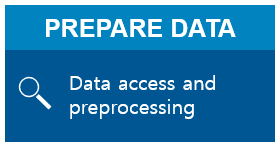

### Load and Preprocess Data

load PhysionetData.mat

This adds two variables to our workspace:

- `Signals` - cell array that holds ECG Signals

- `Labels` - categorical array that holds corresponding ground-truth labels

Signals(1:5)

ans = 5×1 cell array
    {[                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                   -127 -162 -197 -229 -245 -254 -261 -265 -268 -268 -267 -265 -263 -260 -256 -253 -249 -247 -245 -243 -241 -238 -236 -234 -232 -231 -230 -229 -229 -229 -229 -230 -230 -230 -229 -229 -227 -225 -221 -218 -215 -213 -213 -213 -212 -211 -210 -209 -206 -203 -201 -198 -198 -200 -204 -210 -216 -224 -233 -243 -253 -262 -270

Labels(1:5)

ans = 5×1 categorical array
     N 
     N 
     N 
     A 
     A 


summary(Labels)


Labels: 5788×1 categorical

     A                 738 
     N                5050 
     <undefined>         0 


As we can see in the preview, the signal length varies (see `Signals` variable). Let's create a [histogram](https://uk.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html) that shows the length of the signals.

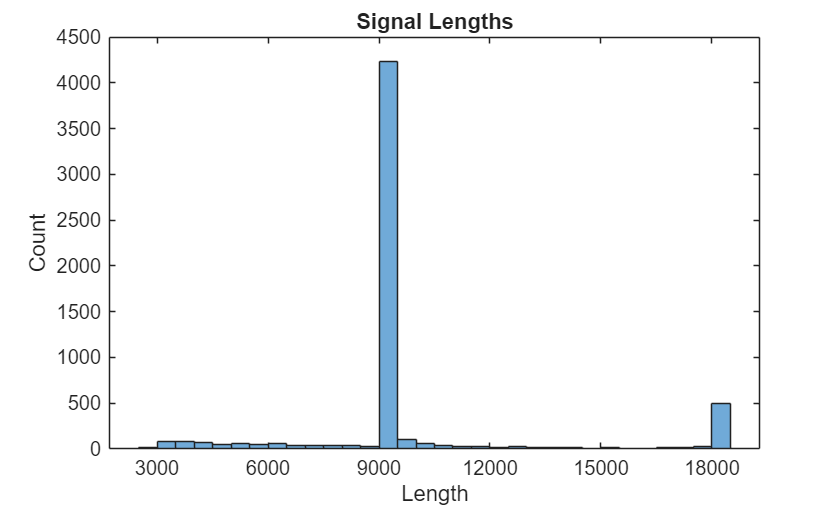

figure
plotSignalLengths(Signals)

Most of the ECG signals are 9000 samples long, but there is some variability.

Visualize a segment of one signal from each class.

Here are two common characteristics of AFib signals:

- Spaced out at irregular intervals.

- Lack a P wave, which pulses before the QRS complex in normal heartbeat.

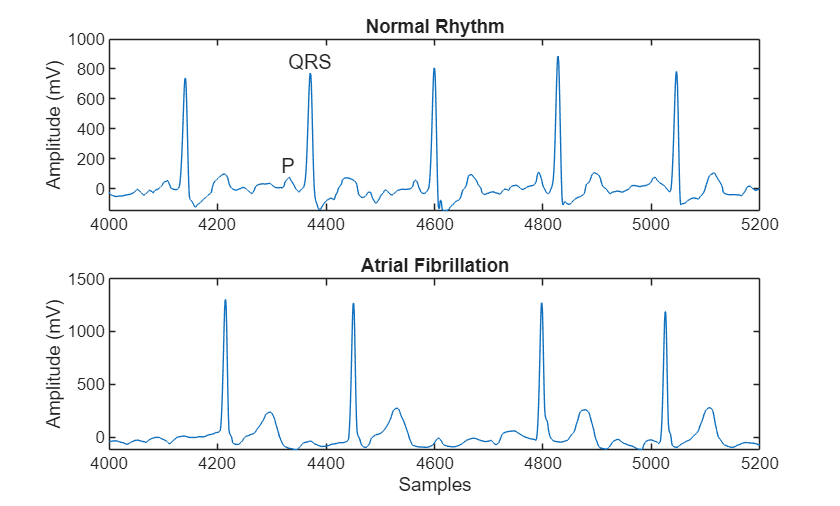

visualizeECGSignals(Signals)

Since the ECG Signals are different lengths, we need to first pad and truncate them so they are all 9000 samples long. 

The function `segmentSignals` ignores signals with fewer than 9000 samples. If the signal is over 9000 samples, `segmentSignals` breaks it into as many 9000-sample segments as possible and ignores the remaining samples.

For example, a signal with 18500 samples becomes two 9000-sample signals and the remaining 500 samples are ignored.

[Signals,Labels] = segmentSignals(Signals,Labels);

### Feature generation

Although a deep neural network was originally designed to work on raw data, better results can be achieved when features are extracted/generated from signal data. In this example, we will transform the signals into images using wavelet transform technique.

If we want to compute the wavelet transform on multiple signals, using a precomputed filter bank can greatly speed up the process.

sig = Signals{1, :};
signalLength = length(sig);
Fs = 128;
fb = cwtfilterbank('SignalLength', signalLength, 'SamplingFrequency', Fs, 'VoicesPerOctave', 48);
[wt, f] = fb.wt(sig);

We can also plot the continuous wavelet transform and scalogram.

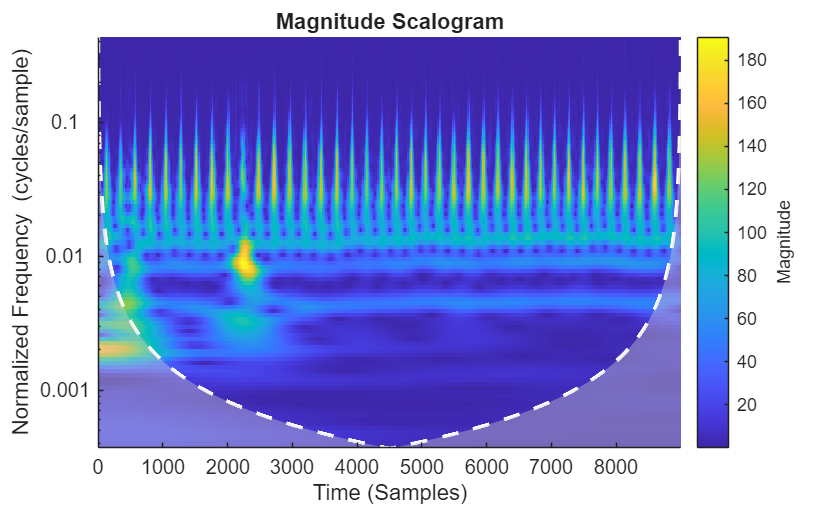

cwt(Signals{1, 1});

Note: We generated Time-Frequency Visualizations for all signals using the [`PrepareCWTImages.mlx`](matlab:edit('PrepareCWTImages.mlx');) script. The images are saved in 'dataCNN' folder.

### Prepare Data for Training

First, we will use an [imageDatastore](https://uk.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) to access the data, resize it (using `readFcn`) and label it (by choosing `foldernames` as `LabelSource`). Then we will use the command [splitEachLabel](https://uk.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.spliteachlabel.html) to split our data set into two subsets (train and test set) so we can evaluate the performance of the model. The train set will be used to train the model while the test set will be used after the training to evaluate the performance on this new (unseen) data.

It is recommended to use between 60 and 90% of the entire data for training and the rest for testing.

In this example, we will use 80% of data for training and remaining for testing.

% make sure you are in Exercises folder
filepath = ['Additional Files' filesep 'dataCNN']; 

allImages = imageDatastore(filepath, 'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');
[trainingImages, testImages] = splitEachLabel(allImages, 0.8, 'randomize');

## Train Model

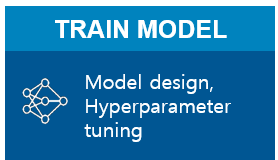

### Option 1: Train using Deep Network Designer

We will apply a technique called [Transfer Learning](https://uk.mathworks.com/discovery/transfer-learning.html) which comprises of using a pre-trained network modified to the specific task.

deepNetworkDesigner

Note: We will perform this step of the workflow in the [Deep Network Designer App](https://www.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html). Alternatively, you can do it programmatically (see Option 2).

#### Step 1: Import ResNet18

You can find the Deep Network Designer in the APP tab (click on ) or call the command [deepNetworkDesigner](https://uk.mathworks.com/help/deeplearning/gs/get-started-with-deep-network-designer.html).

Load a pre-trained [ResNet-18](https://www.mathworks.com/help/deeplearning/ref/resnet18.html) network by selecting it from the Deep Network Designer Start Page. (If you need to download the network, then click **Install** to open the Add-On Explorer.)

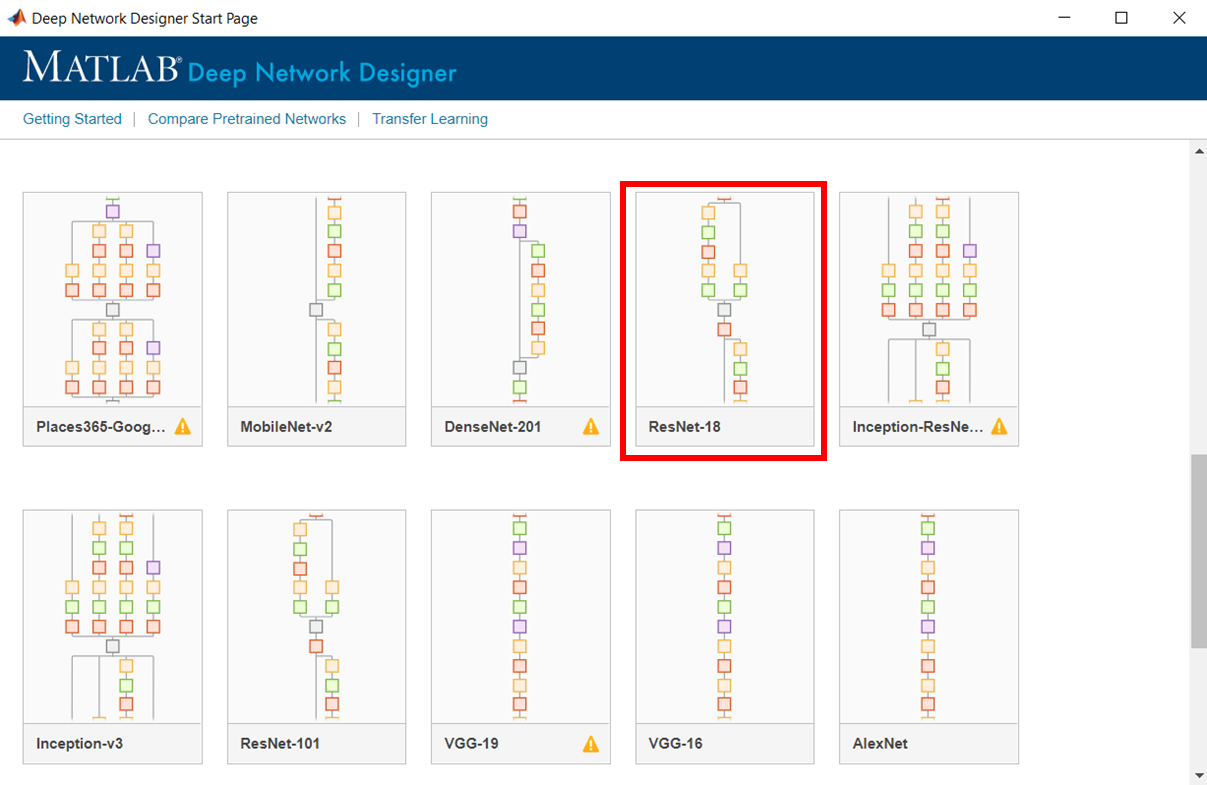

#### Step 2: Modify ResNet

In transfer learning, the majority of the layers stay the same. We need to modify the last 3 layers to fit our specific dataset. 

In the tab `Designer`, do the following:

- Remove the last three layers in the network

- Add in a new Fully Connected Layer, Softmax Layer, and Classification Layer

- In the **fullyConnectedLayer**, change **OutputSize = 2 **(as we have 2 classes: Normal and Afib)

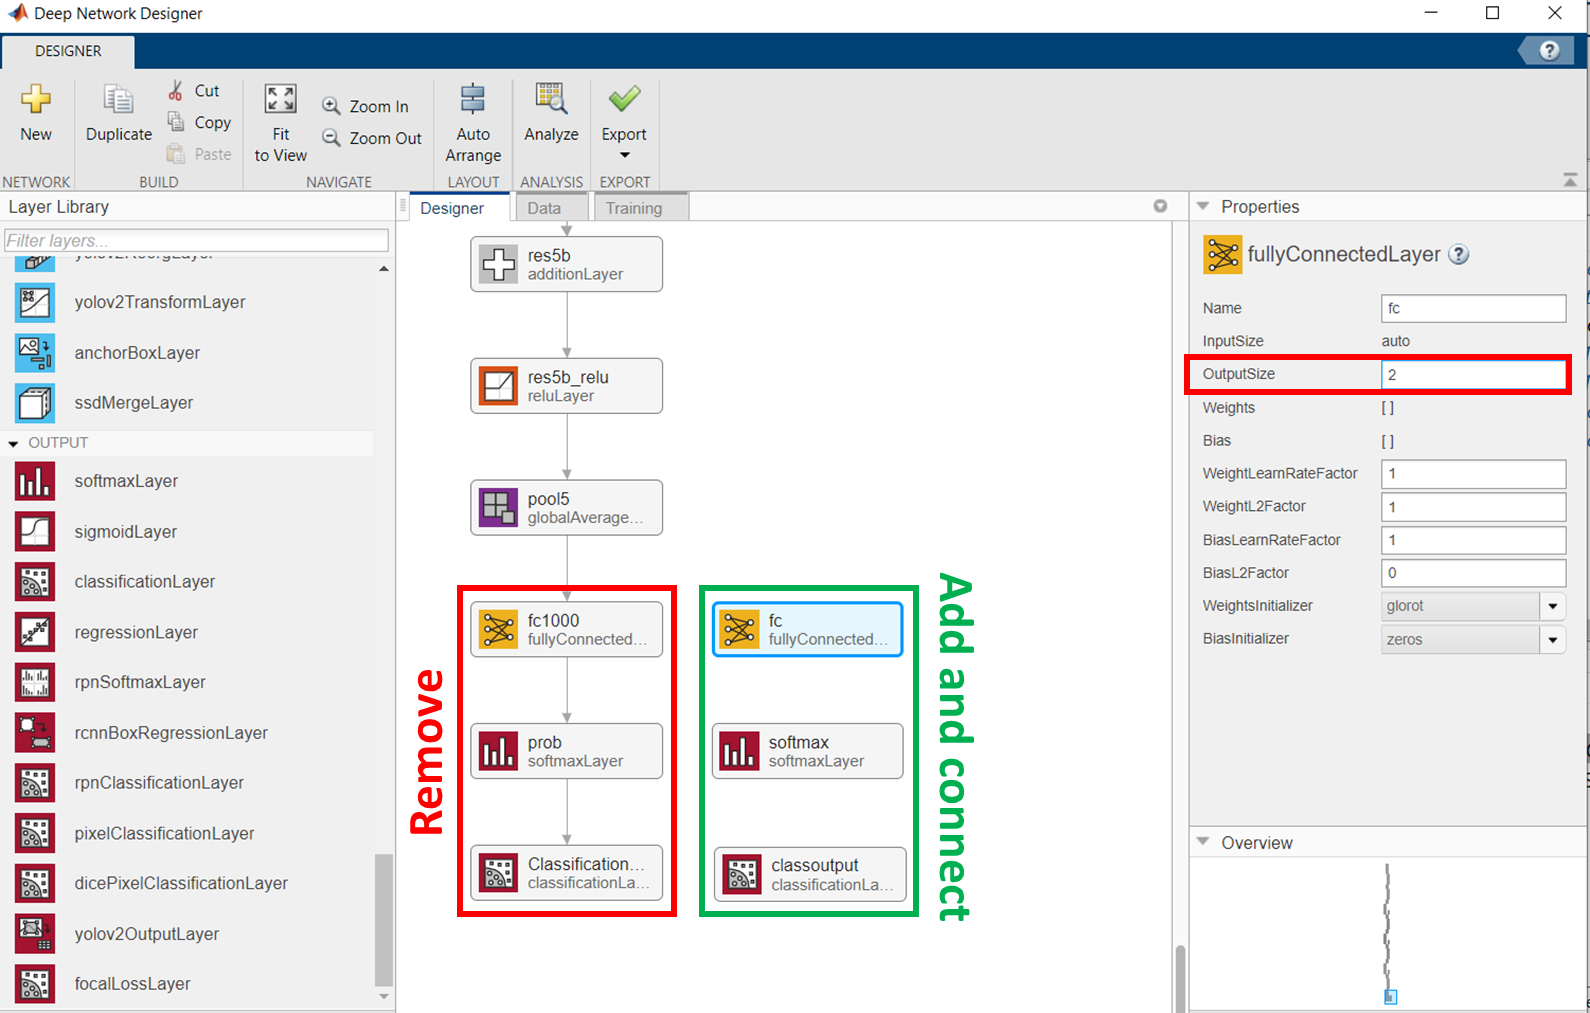

#### Step 3: Specify Data for Training and Validation

In the tab` Data`, click on `Import Data` and choose `Import Image Data`.

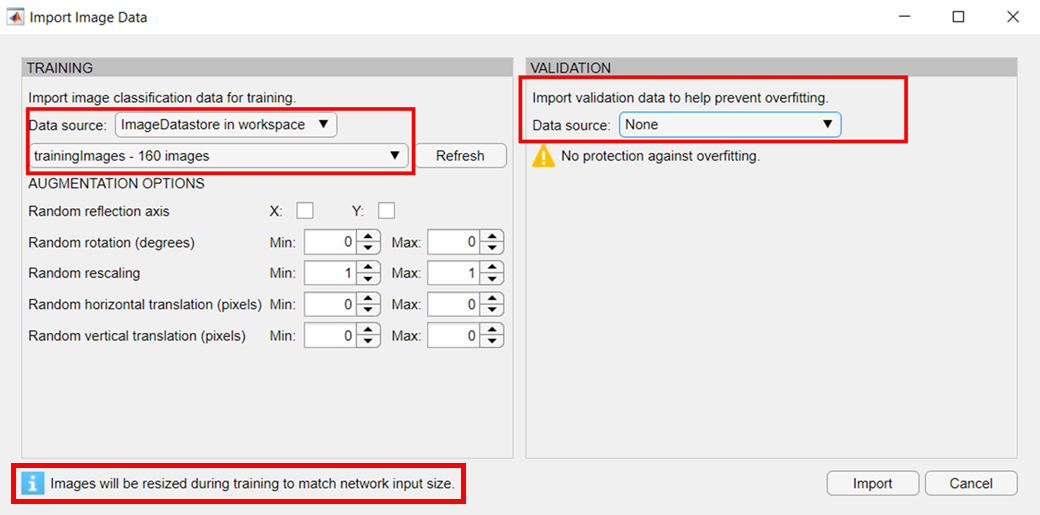

#### Step 4: Adjust Training Options

In the tab `Training`, click on `Training Options` and choose the following hyperparameters:

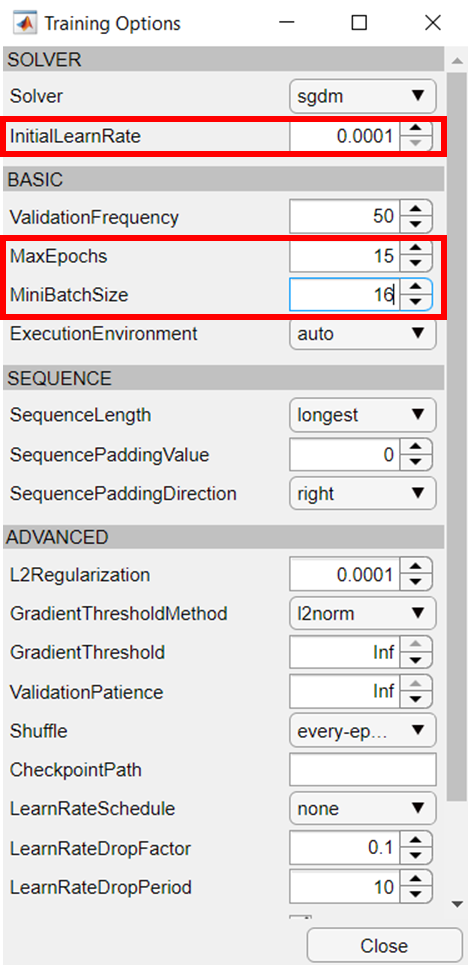

#### Step 5: Train the Network

In the tab `Training`, click on `Train` to train the network.

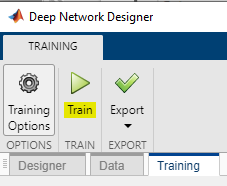

Your training progress should look similar to this:

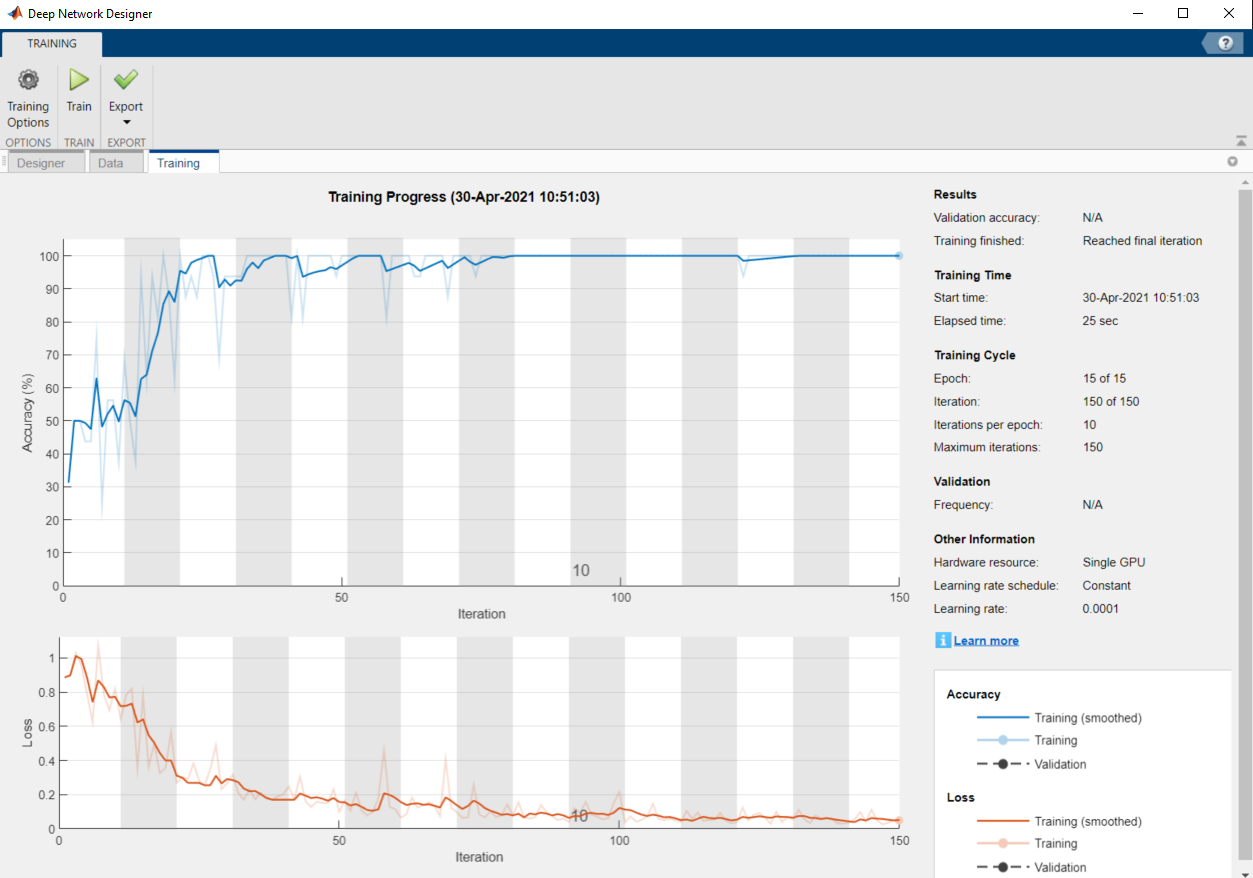

Note: This might take a few minutes, depending on your hardware. We recommend to use a GPU.

**Step 6: Export the network**

In the tab `Training`, click on `Export` to export the trained network and the results.

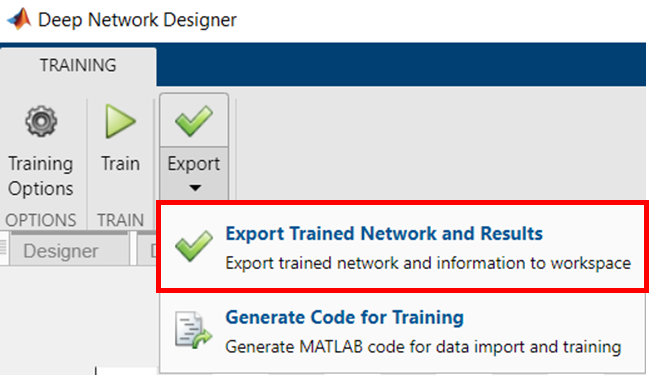

*!!! Rename the exported network (*`trainedNetwork_1`*) to* `ECGNet`

### Evaluating the trained model 

Use the trained model (`ECGNet`) to classify the test image set (`testImages`).

predictedLabels = classify(ECGNet, testImages);

Unrecognized function or variable 'ECGNet'.

Calculate the test accuracy and show the confusion matrix.

accuracy = sum(predictedLabels == testImages.Labels) / numel(predictedLabels);
figure
ccLSTM = confusionchart(testImages.Labels,predictedLabels);
ccLSTM.Title = ("Confusion Matrix, Accuracy " + accuracy*100 + "%"');
ccLSTM.ColumnSummary = 'column-normalized';
ccLSTM.RowSummary = 'row-normalized';

### Option 2: Train programmatically

MATLAB can train models programmatically as well, allowing the user to customize several hyperparameters.

We'll load in the pretrained `resnet18` network. We need to modify our network for our purposes, this step is called transfer learning. Because ResNet-18 is a [DAG-network](https://www.mathworks.com/help/deeplearning/ref/dagnetwork.html), we need to create a [layergraph](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layergraph.html) first, in order to be able to modify it.

In order to retrain just the last few layers, we will replace them with a new `fullyConnectedLayer`, a new `softmaxLayer,` and a new `classificationLayer`.

net = resnet18;

lgraph = layerGraph(net);

% create new layers
new_fc = fullyConnectedLayer(2, 'Name','new_fc');
new_sm = softmaxLayer('Name', 'new_softmax');
new_cl = classificationLayer('Classes', {'A', 'N'}, 'Name', 'new_cl');

% replace layers
lgraph_new = replaceLayer(lgraph,'fc1000',new_fc);
lgraph_new = replaceLayer(lgraph_new, 'prob', new_sm);
lgraph_new = replaceLayer(lgraph_new, 'ClassificationLayer_predictions', new_cl);

Use the following [training options](https://uk.mathworks.com/help/deeplearning/ref/trainingoptions.html) and save them to variable `opts`:

- `InitialLearnRate 0.0001`

- `MaxEpochs        15 `

- `MiniBatchSize    16 `

opts = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.0001, ...
    'MaxEpochs', 15, ...
    'MiniBatchSize', 16, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment',"auto", ...
    "Verbose", false);

Now train the network and save it to variable `ECGNet`.

ECGNet = trainNetwork(trainingImages, lgraph_new, opts);

### Evaluating the trained model 

Use the trained model (`ECGNet`) to classify the test image set (`testImages`).

predictedLabels = classify(ECGNet, testImages);

Calculate the test accuracy and show the confusion matrix.

accuracy = sum(predictedLabels == testImages.Labels) / numel(predictedLabels);
figure
ccLSTM = confusionchart(testImages.Labels,predictedLabels);
ccLSTM.Title = ("Confusion Matrix, Accuracy " + accuracy*100 + "%"');
ccLSTM.ColumnSummary = 'column-normalized';
ccLSTM.RowSummary = 'row-normalized';

## Summary and Next steps

In this example we applied wavelet transform to convert ECG waveforms into images and used a convolution neural network for classification. We used the transfer learning technique to adjust the deep network from the images it was trained on to the scalogram images representing ECG waveforms.

The accuracy is lower than 90% with a transformed ResNet and is below what we achieved even with standard statistical features and machine learning, but the data set is on the small end for applying deep learning, and more complex networks typically achieve higher accuracies. Here’s some additional steps you could try to improve accuracy:  

- Better network with images: Use a higher accuracy pretrained network as starting point

- Work with signals: Apply an [LSTM network](https://uk.mathworks.com/help/deeplearning/ug/long-short-term-memory-networks.html) architecture that directly models the time series characteristics of signals like ECG (instead of stepping over into frequency space). An example can be found [here](https://www.mathworks.com/help/signal/ug/classify-ecg-signals-using-long-short-term-memory-networks.html).

- Optimization and hyperparameter tuning: Apply [data augmentation](https://uk.mathworks.com/help/deeplearning/ug/image-augmentation-using-image-processing-toolbox.html) and other deep network optimization techniques (e.g. [Bayes Optimization](https://uk.mathworks.com/help/deeplearning/ug/deep-learning-using-bayesian-optimization.html)), including hyperparameter tuning

More details can be found [here (Deep Learning Tips & Tricks)](https://uk.mathworks.com/help/deeplearning/ug/deep-learning-tips-and-tricks.html).